%%create datastore for all images and split into training,validation,and testing data
root = fullfile('M:\Documents\MATLAB\BME3053C final project\brain_tumor_dataset');
MRIs = imageDatastore(root,'IncludeSubFolders',true,'LabelSource','foldernames');
[train, val, test] = splitEachLabel(MRIs, 0.7,0.1,0.2, 'randomized');

%%resize images and preprocess
imageSize = [227 227 3];
autrain = augmentedImageDatastore(imageSize,train,'ColorPreprocessing', 'gray2rgb');
auval = augmentedImageDatastore(imageSize,val,'ColorPreprocessing', 'gray2rgb');
autest = augmentedImageDatastore(imageSize,test,'ColorPreprocessing', 'gray2rgb');
[data,info]=read(autrain);
[data,info]=read(autest);


%%create variable to store trained network and results
load net.mat;

%%calculate accuracy of model on test set
YPred = classify(net,autest);
YValidation = test.Labels;

accuracy = sum(YPred == YValidation)/numel(YValidation)

accuracy = 0.9412

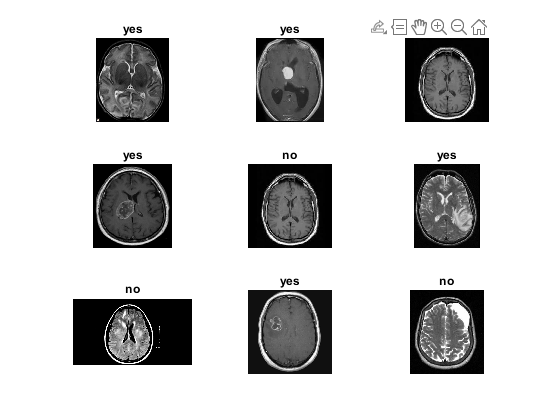

%%Show sample images with their predicted labels from the model

ii = randi(numel(test.Labels),1,9);

figure()
for i = 1:numel(ii)
    subplot(3,3,i)
    I = readimage(test,ii(i));
    label = YPred(ii(i));
    
    set(gcf,'visible','on')
    imshow(I)
    title(label)
end

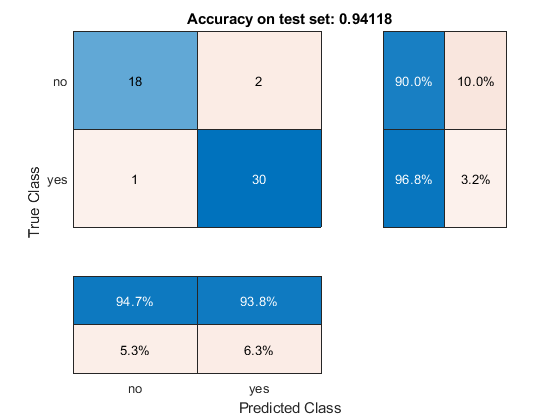

%%visualize accuracy of classification on test set
figure(2)
confusionchart(YValidation,YPred,'RowSummary','row-normalized','ColumnSummary','column-normalized','Title','Accuracy on test set: ' + string(accuracy));

confusionmatrix = confusionmat(YValidation,YPred);
accurate = diag(confusionmatrix);

%calculate true positive and false positive rates
tp = confusionmatrix(4);
fp = confusionmatrix(3);
tn = confusionmatrix(1);
fn = confusionmatrix(2);
TPR = tp/(tp+fp);
FPR = fp/(tp+fp);
TNR = tn/(tn+fn);
FNR = fn/(fn+tn);

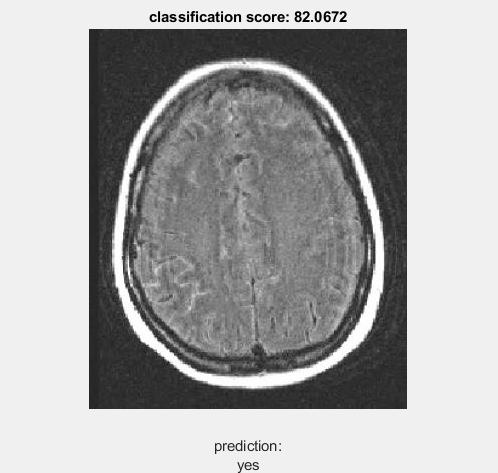

%%input specific image and predict label
figure(3)
img = input('Enter full image name: ','s');
img = imread(img);
img2 = imresize(img,'OutputSize',[227 227]);
[prediction, percent] = classify(net,img2);
set(gcf,'visible','on')
imshow(img);
percent = double(percent*100);

%for images in the "yes" category, index of percent() should be 2; for
%"no", index should be 1
title(['classification score: ' num2str(percent(2))])
xlabel(['prediction: '  prediction]);